# *Population Models*

The file `population.xlsx` contains the estimated world population (in thousands) every other year from 1950 to 2014.

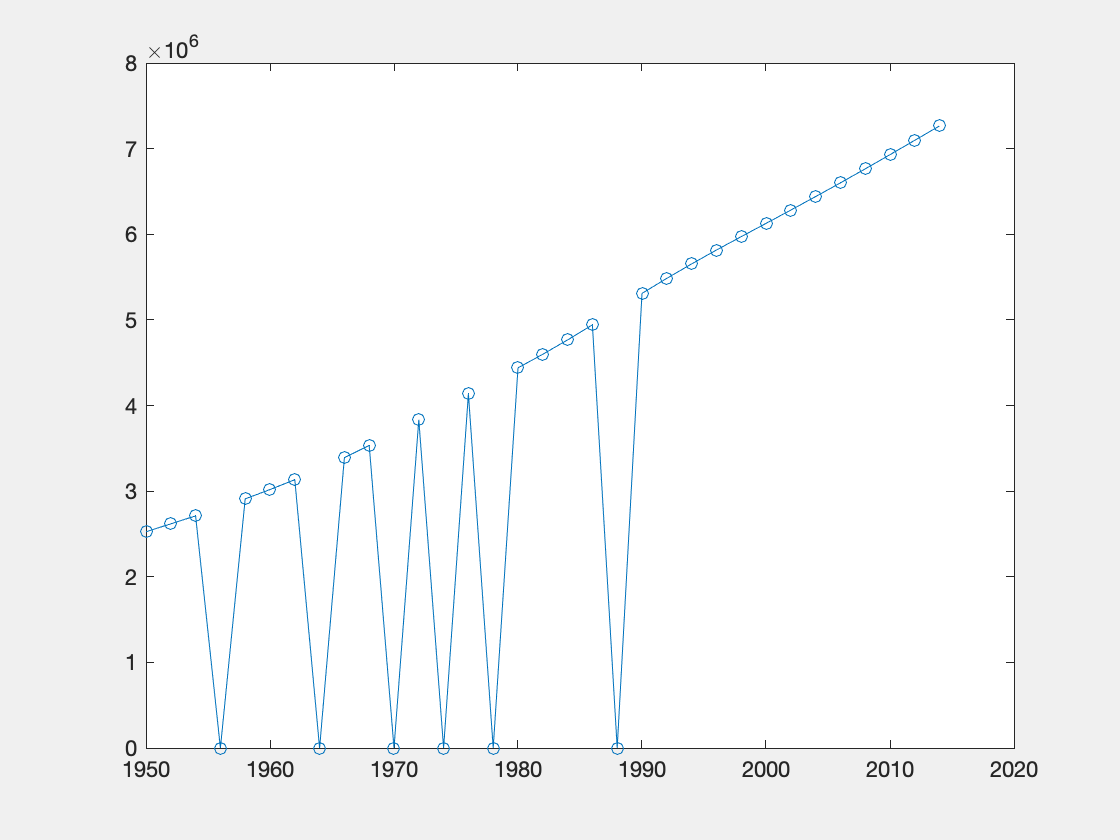

% To see the plot answers, run this section.

openfig('worldpop1.fig','visible'); % Q1 answer

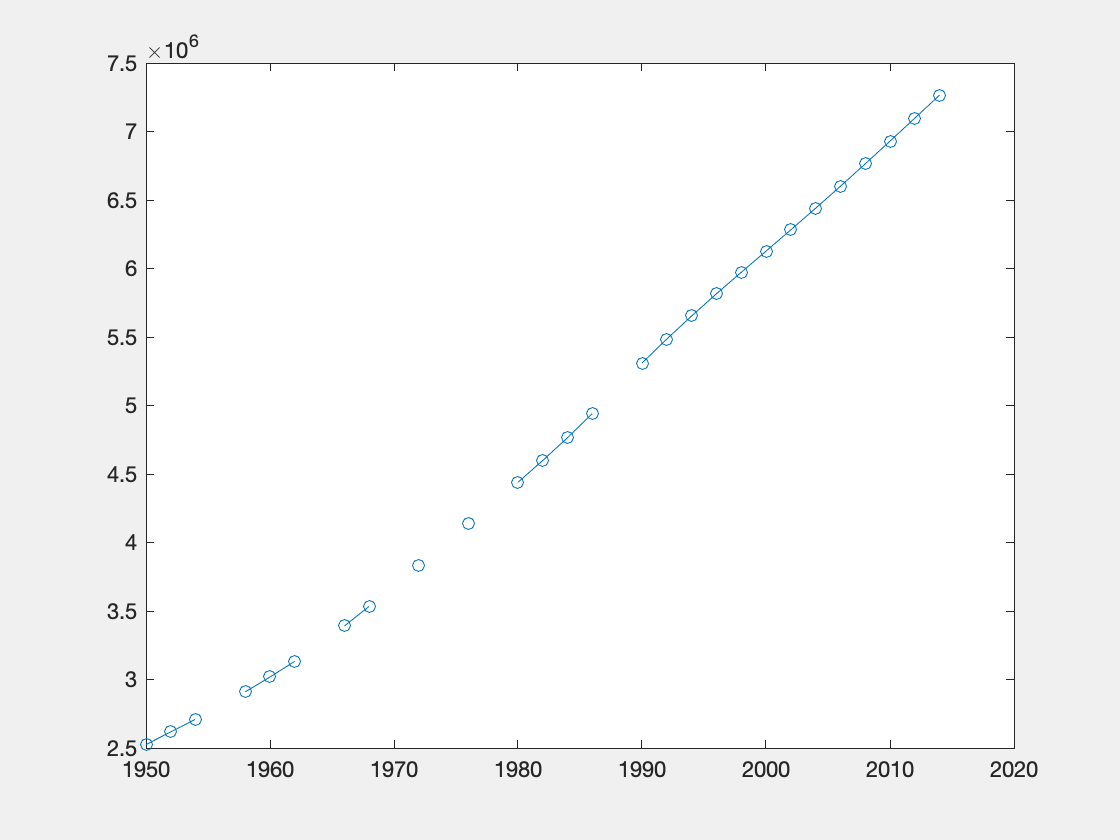

openfig('worldpop2.fig','visible'); % Q2 answer

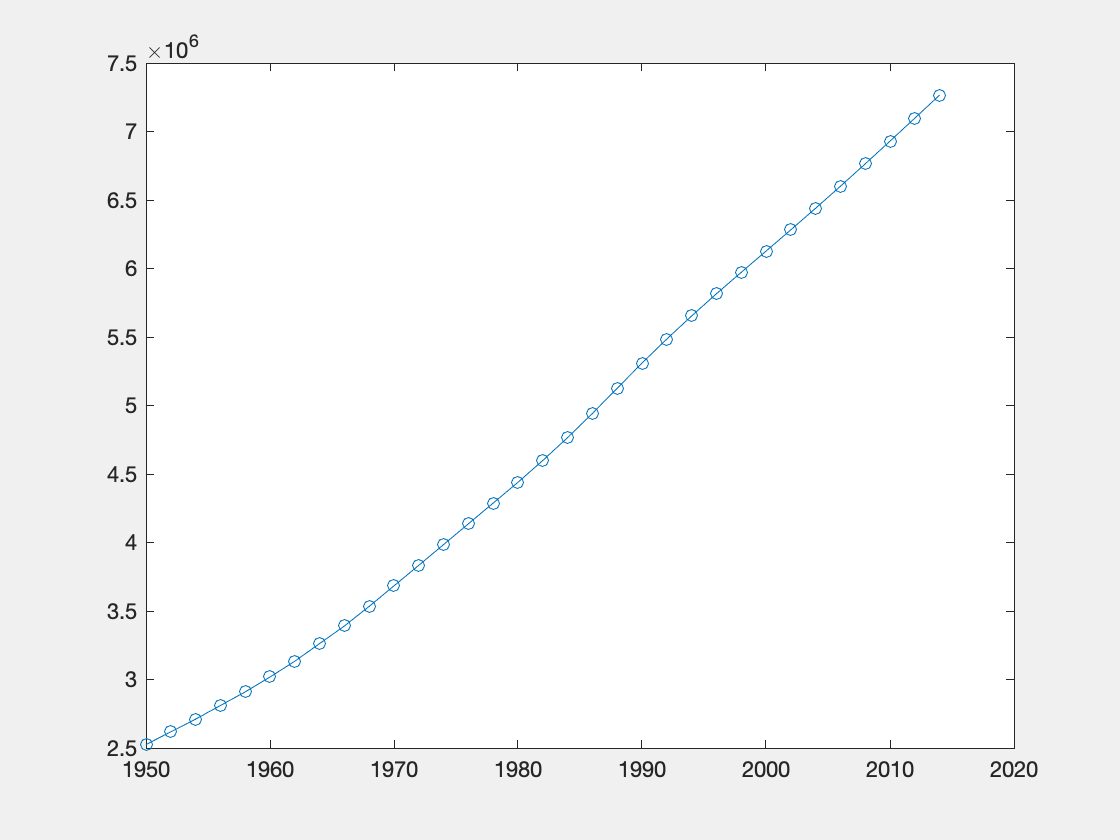

openfig('worldpop3.fig','visible'); % Q3 answer

## 1. Read and plot data

Import the world population data in `population.xlsx` as a table. Plot the data as a function of year with circular markers.

population = readtable("population.xlsx")

population = 33×2 table
    Year    Population
    ____    __________

    1950    2.5251e+06
    1952    2.6179e+06
    1954    2.7107e+06
    1956             0
    1958    2.9097e+06
    1960    3.0183e+06
    1962    3.1336e+06
    1964             0
    1966    3.3907e+06
    1968     3.534e+06
    1970             0
    1972    3.8336e+06
    1974             0
    1976    4.1365e+06
    1978             0
    1980    4.4396e+06


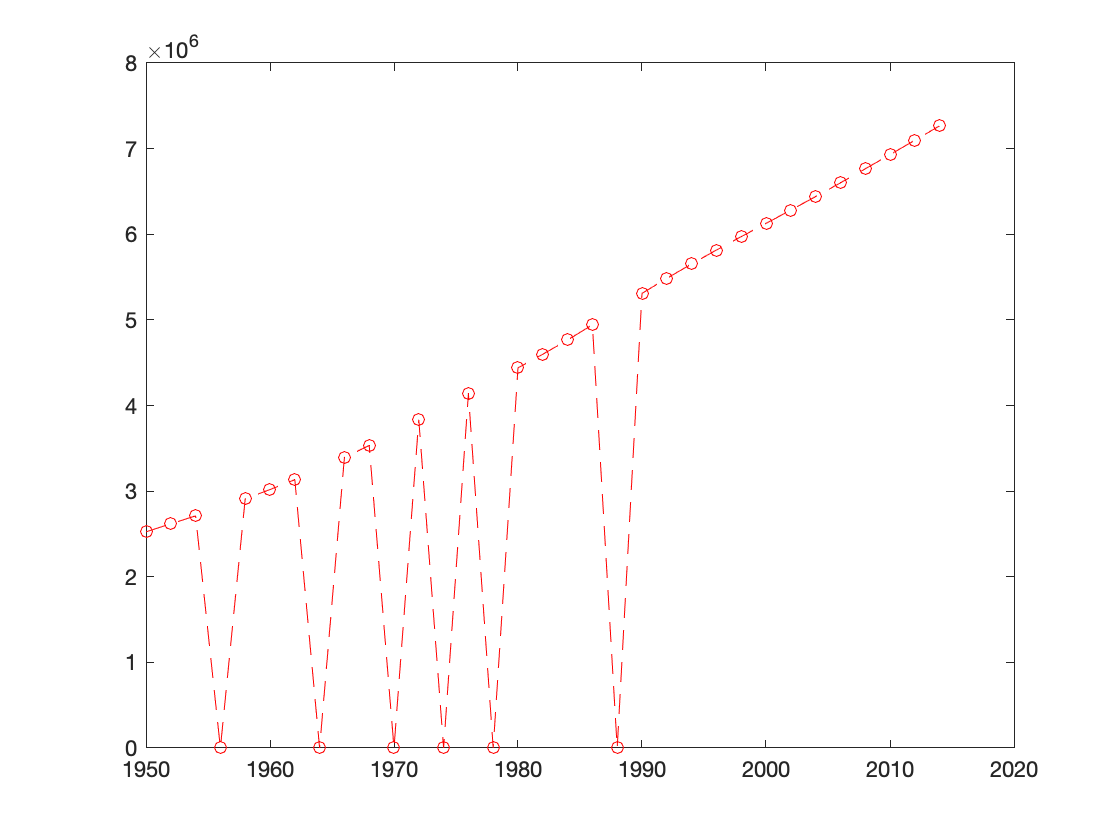

plot(population.Year,population.Population,"r--o")

## 2. Replace incorrect values with NaN

Note that a population value of 0 is clearly a missing value. Replace the zeros with `NaN `by using` standardizeMissing.` Replot the result.

% doc standardizeMissing
population2 = standardizeMissing(population,{0 'N/A'})

population2 = 33×2 table
    Year    Population
    ____    __________

    1950    2.5251e+06
    1952    2.6179e+06
    1954    2.7107e+06
    1956           NaN
    1958    2.9097e+06
    1960    3.0183e+06
    1962    3.1336e+06
    1964           NaN
    1966    3.3907e+06
    1968     3.534e+06
    1970           NaN
    1972    3.8336e+06
    1974           NaN
    1976    4.1365e+06
    1978           NaN
    1980    4.4396e+06


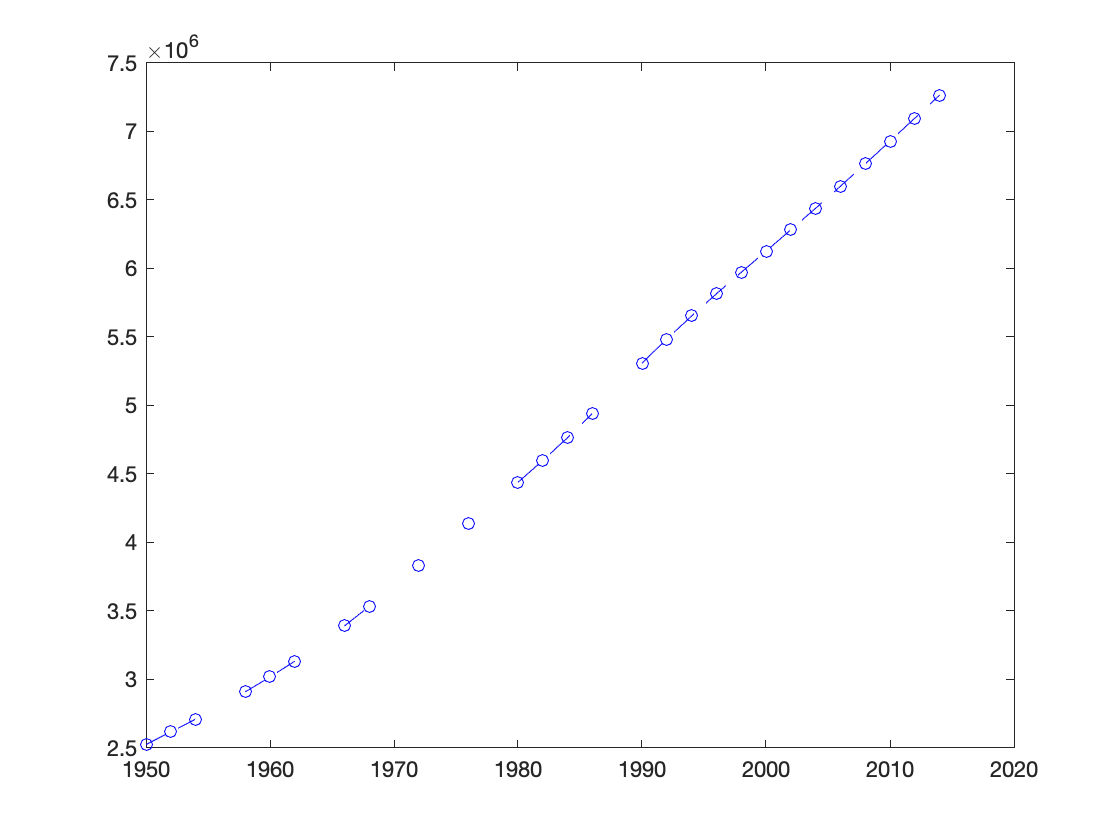

plot(population2.Year,population2.Population,"b--o")

## 3. Fill missing values

Use `fillmissing` to replace the missing values with linearly interpolated values. Replot the result

% doc fillmissing
population3 = fillmissing(population2,'linear')

population3 = 33×2 table
    Year    Population
    ____    __________

    1950    2.5251e+06
    1952    2.6179e+06
    1954    2.7107e+06
    1956    2.8102e+06
    1958    2.9097e+06
    1960    3.0183e+06
    1962    3.1336e+06
    1964    3.2621e+06
    1966    3.3907e+06
    1968     3.534e+06
    1970    3.6838e+06
    1972    3.8336e+06
    1974    3.9851e+06
    1976    4.1365e+06
    1978    4.2881e+06
    1980    4.4396e+06


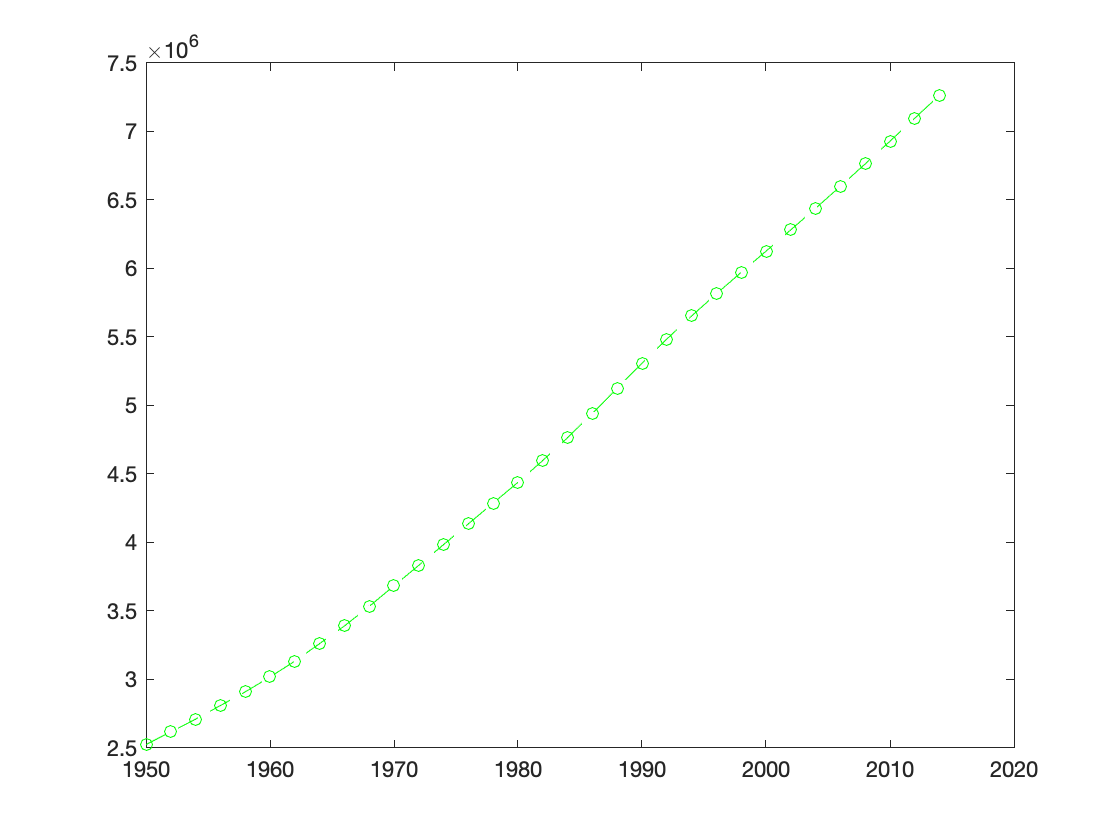

plot(population3.Year,population3.Population,"g--o")